%pg 18
tau1=0.1;
tau2=1;
K=1;
p=tf('p');

L=K/(p*(1+tau1*p)*(1+tau2*p))


L =
 
            1
  ---------------------
  0.1 p^3 + 1.1 p^2 + p
 
Continuous-time transfer function.
Model Properties


%getting eq ga

pg11 (saturated fn)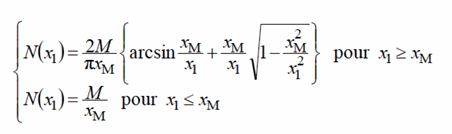

%N=(2*M/pi*xM)*arcsin(xM/x1+(xM/x1)*sqrt(1-(x^2/x1^2)));
%nqyst()
%hold all
%hold off

%plot nyqust
%plotting nichols

testing

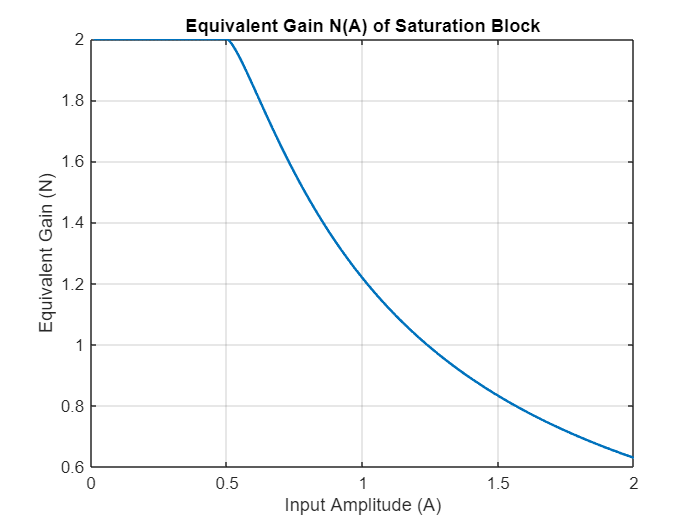

% --- Saturation Parameters ---
M = 1;      % Saturation output limit (+/- M)
xM = 0.5;   % Input limit for the linear region

% --- Amplitude Range for Analysis ---
A = linspace(0.01, 4*xM, 400); % Range of input amplitudes

% --- Calculate Describing Function N(A) ---
N = zeros(size(A));

% For inputs within the linear region (A <= xM), gain is constant
linear_idx = (A <= xM);
N(linear_idx) = M / xM;

% For inputs causing saturation (A > xM), use the describing function formula
saturated_idx = (A > xM);
alpha = xM ./ A(saturated_idx);
N(saturated_idx) = (2*M/pi) * ( (1/xM) * asin(alpha) + (1./A(saturated_idx)) .* sqrt(1 - alpha.^2) );

% --- Plot the Equivalent Gain ---
figure;
plot(A, N, 'LineWidth', 1.5, 'Color', [0, 0.4470, 0.7410]);
title('Equivalent Gain N(A) of Saturation Block');
xlabel('Input Amplitude (A)');
ylabel('Equivalent Gain (N)');
grid on;

%trying N(x,w)
x=0.1:0.1:100;
if x1>=xM
    parenthesis=asin(xM/x1)+xM/x1*sqrt(1-(xM/x1)^2);
    N=( 2*M/(pi*xM) )*parenthesis;
else %x1<=xM
    N=M/xM;
end

N=length(x);
% --- Generate Nyquist Plot ---
figure;
nyquist(L);
hold on;
plot(-1./N, zeros(size(N)), 'r--', 'LineWidth', 1.5);
